# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.14 BP神经网络图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

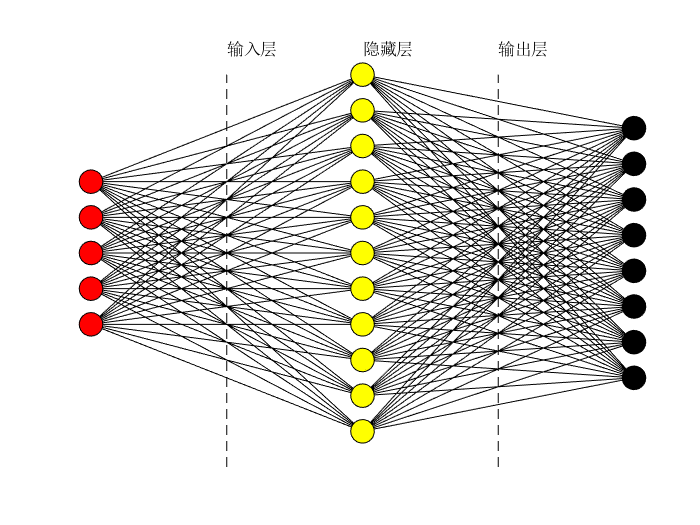

clear;clc;close all;
figure;
x1 = ones(1, 5);
x2 = 2 * ones(1, 11);
x3 = 3 * ones(1, 8);
% 神经元位置
y1 = 4:8;
y2 = 1:11;
y3 = 2.5:9.5;
% 神经元之间的连线
for i = 1:5
    for j = 1:11
        plot([x1(i), x2(j)], [y1(i), y2(j)], 'k');
        hold on
    end
end
for i = 1:11
    for j = 1:8
        plot([x2(i), x3(j)], [y2(i), y3(j)], 'k');
    end
end
% 神经元
scatter(x1, y1, 200, 'k', 'MarkerFaceColor', 'r');
scatter(x2, y2, 200, 'k', 'MarkerFaceColor', 'y');
scatter(x3, y3, 200, 'k', 'MarkerFaceColor', 'k');
plot([1.5, 1.5], [0, 11], 'k--');
plot([2.5, 2.5], [0, 11], 'k--');
hold off
axis off
% 文本
text(1.5, 11.75, '输入层');
text(2, 11.75, '隐藏层');
text(2.5, 11.75, '输出层');